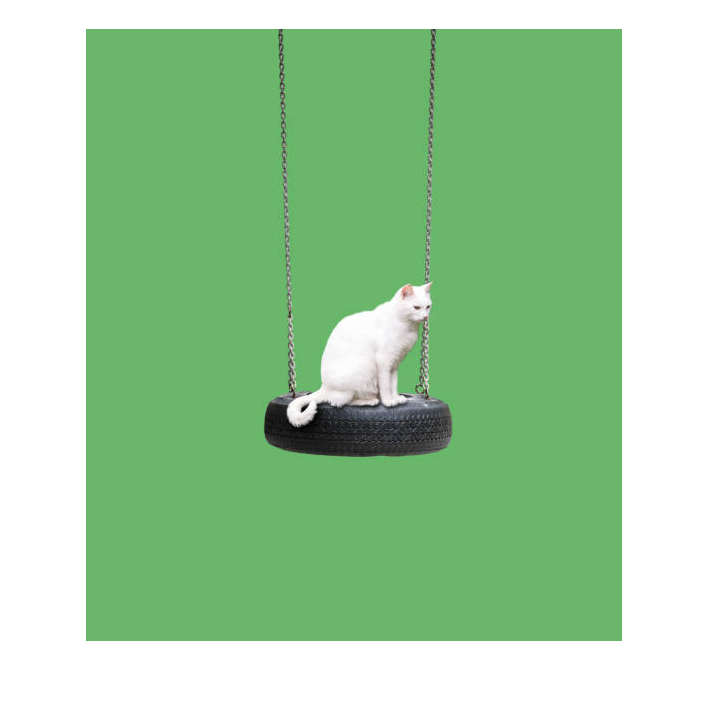

chat = imread("chat.jpg");
arbre = imread("arbre.jpg");
imshow(chat)

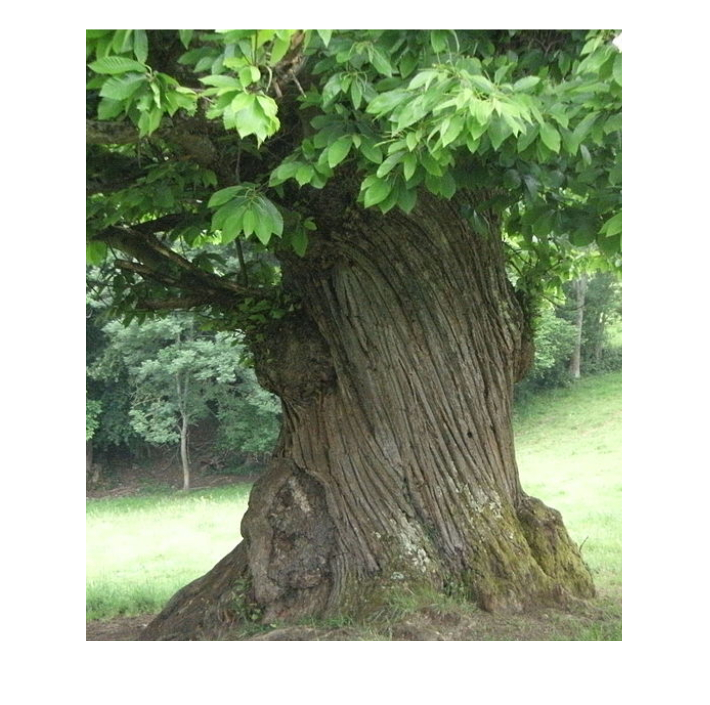

imshow(arbre)

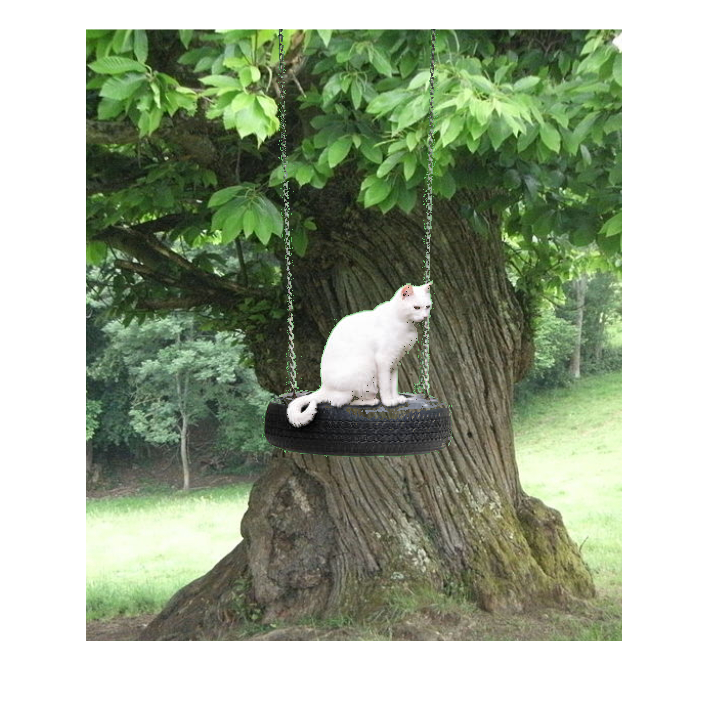

chat_r = chat(:,:,1);
chat_g = chat(:,:,2);
chat_b = chat(:,:,3);
fond_r = chat(1,1,1);
fond_g = chat(1,1,2);
fond_b = chat(1,1,3);
marge_r = 10;
marge_g = 0;
marge_b = 10;

mask = (chat_r > fond_r + marge_r | chat_r < fond_r - marge_r) ...
    & (chat_b > fond_b + marge_b | chat_b < fond_b - marge_b ) ...
    & (chat_g > fond_g + marge_g | chat_g < fond_g - marge_g);

rendu = arbre.*cast(~mask,class(arbre)) + chat.*cast(mask, class(chat));
imshow(rendu)